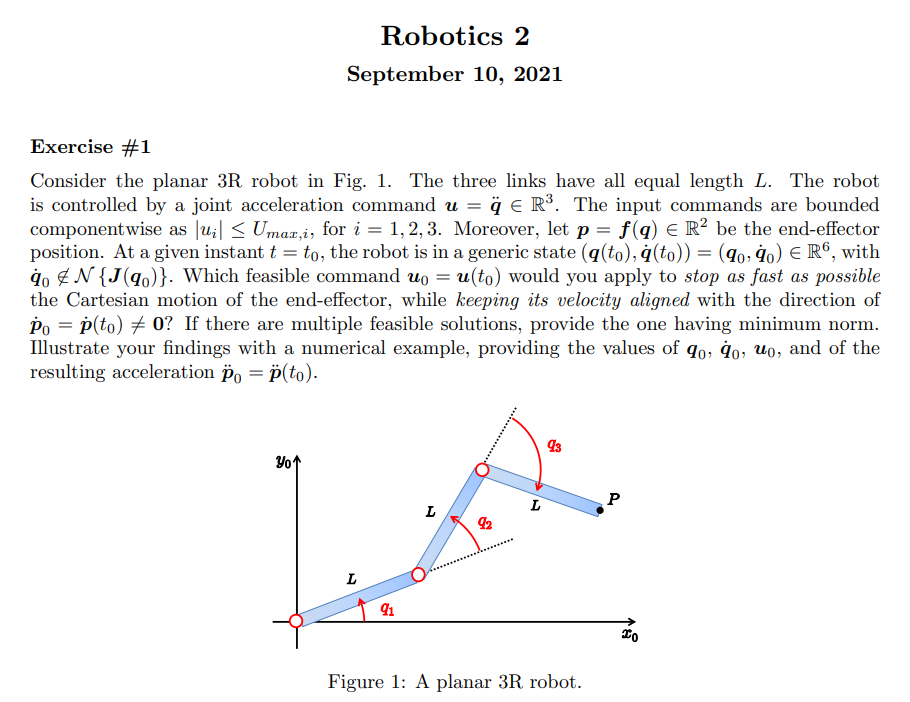

% % % This part is isolated from previous sectionclear;clc
% clear all, close all, clc;
% % syms k q1(t) q2(t) q3(t)
% sigmaD = [0,0,0];
% n = length(sigmaD);
% % t = sym('t', 'real');
% q = sym('q_', [n 1],'real');
% q_d= sym('q_d_', [n 1],'real');
% q_dot = sym('q_dot_', [n 1],'real');
% q_ddot = sym('q_ddot_', [n 1],'real');
% %
% dc = sym('dc', [n 1],'real');
% % dc(6)=dc(6)
% % k = sym('k', [n 1],'real');
% l = sym('l', [n 1],'real');
% m = sym('m', [n 1],'real');
% m_p = sym('m_p','real');
% %m(2)=m(2)+m_p
% I = sym('I', [n 1],'real');
% alpha_angle=sym('alpha','real')
% g0 = sym('g0','real');
% g=[0,-g0,0]';

% R2Robot=['rrr';'xxx';sigmaD]
% z = Gen_param(n);
% z.sigmaD=R2Robot;
% z.l=l;
% 
% z.q=q;
% z.q_dot=q_dot;
% 
% z.g=g;
% 
% z.dc=dc;
% z.m=m;
% z.I=I;
% z.methodD=1%2=with DH table
% % z.dhTable=dhTable
% z.firstParam='alpha';
% % z.rc=[]
% % z.movingframes=[]
% z.angle_=sym(zeros(1,n));
% % z.opt_expr={[l(1)+q(2)],[q(2)]};
% % z.rcdefined=true;
% z.prismatic_CoM_method(2)=2;
% z.xyonly=true

% % 
% % [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE2(z)
% % 

% % 
% % PC_EEShort.J
% % PC_EEShort.f

% % VarShortRobot.M
% % angle_desired=[0,0]
% % % xyonly=true
% [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot,PC_EE]= getGenericPC_EE2(z)

% PCVar.f_dot
% PC_EEShort.f
% PC_EEShort.J
% f
% J
% PC_EEShort.J_dot_short
% 

## defining Control output

% lambda=sym('lambda','real')
% a_sym=sym('a','real')
% b_sym=sym('b','real')
% u_sym=lambda*a_sym+b_sym
% 
% 

## U_max definition

% U_max=[15,10,10]'*pi
% q_=[0,pi/2,pi/2]'
% q_dot_=0.7*[pi,pi,0]'
% l_=[1,1,1]'
% to_replace=[z.q;z.q_dot;z.l]
% to_replace_=[q_;q_dot_;l_]

## Replacing values

% J0_=subs(J,to_replace,to_replace_)
% p0_=J0_*q_dot_
% f0_fot_=subs(PCVar.f_dot,to_replace,to_replace_)
% 
% J0_dot_=subs(PC_EE.J_dot,to_replace,to_replace_)
% J0_pinv_=pinv(J0_)
% h0_=J0_dot_*q_dot_
% 

## getting u

% a_=-J0_pinv_*J0_*q_dot_
% b_=-J0_pinv_*h0_
% a_=vpa(a_)
% b_=vpa(b_)
% 
% % with complete computations it follows manually

## Exercise 2

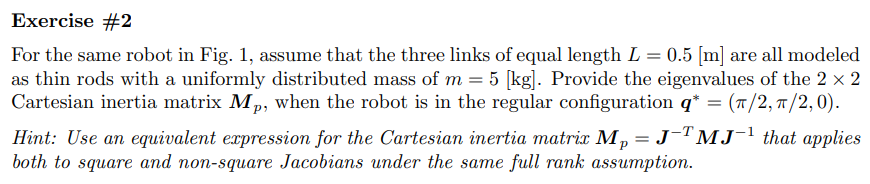

% % % close all
% % % % Lengths just to test
% % % d1_=10;
% % % d2_=10;
% % % a2_=10;
% % % % % De Luca's approach
% % %  links = [
% % %     Revolute('a', 0, 'alpha', -pi/2 ,'d', 1);
% % %     Revolute('a', a2_, 'alpha',0,'d', 0);
% % % %     Prismatic('qlim', [0 len1],'alpha',pi/2,'theta',pi);
% % % %     Revolute('a', len1, 'alpha', 0 ,'d', 0);
% % %     ];
% % % % 
% % %  c600 = SerialLink(links);
% % %  c600.teach([0 0],'view','x');
% % % % c600.plot([0  pi/2 20 0],'view','x')
% % % clear

% 
% % This part is isolated from previous sectionclear;clc
% clear all, close all, clc;
% % syms k q1(t) q2(t) q3(t)
% sigmaD = [0,0,0];
% n = length(sigmaD);
% % t = sym('t', 'real');
% q = sym('q_', [n 1],'real');
% q_d= sym('q_d_', [n 1],'real');
% q_dot = sym('q_dot_', [n 1],'real');
% q_ddot = sym('q_ddot_', [n 1],'real');
% %
% dc = sym('dc', [n 1],'real');
% % dc(6)=dc(6)
% % k = sym('k', [n 1],'real');
% l = sym('l', [n 1],'real');
% m = sym('m', [n 1],'real');
% m_p = sym('m_p','real');
% %m(2)=m(2)+m_p
% I = sym('I', [n 1],'real');
% % alpha_angle=sym('alpha','real')
% g0 = sym('g0','real');
% g=[0,0,-g0]';

% R2Robot=['rrr';'xxx';sigmaD]
% z = Gen_param(n);
% z.sigmaD=R2Robot;
% z.l=l;
% z.q=q;
% z.q_dot=q_dot;
% z.q_ddot=q_ddot;
% 
% z.g=g;
% 
% z.dc=dc;
% z.m=m;
% z.I=I;
% z.methodD=1%2=with DH table, 1 normal mode
% % z.dhTable=dhTable
% z.firstParam='alpha';
% % z.rc=[]
% % z.movingframes=[]
% z.angle_=sym(zeros(1,n));
% % z.opt_expr={[l(1)+q(2)],[q(2)]};
% % z.rcdefined=true;
% z.prismatic_CoM_method(2)=2;
% z.xyonly=true
% % q = sym('q', [n,1],'real');
% % qd= sym('qd', [n,1],'real');
% % a = sym('a', [n,1],'real');
% % d = sym('d', [n,1],'real');

% % z.dhTable = [pi/2    , 0     , z.l(1) , q(1);
% %             0       , z.l(2)  , 0   , q(2);]

% % 
% % [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE2(z)
% [Pc,vc,w,T,Ti,M,VarShortRobot,Trans]=getGenericPC2(z)
% % [Pc,vc,w,T,Ti,M] = getGenericPC2_xyz(z)

% Pc
% % vc
% % simplify(collect(expand(vc(:,2)'*vc(:,2)),z.q_dot(1)^2))
% % Ti(1)
% % Ti(2)
% M

## Replacing values

% % U_max=[15,10,10]'*pi
% % q_=[0,pi/2,pi/2]'
% % q_dot_=0.7*[pi,pi,0]'
% l_=[0.5,0.5,0.5]'
% dc_=l_/2
% m=5
% I_=(1/12)*m*(l_.^2)
% m_=[5,5,5]'
% % to_replace=[z.q;z.q_dot;z.l]
% % to_replace_=[q_;q_dot_;l_]
% 
% to_replace  =[z.l;z.dc;z.I;z.m]
% to_replace_ =[l_;dc_;I_;m_]

## Replacing values

% M_=subs(M,to_replace,to_replace_)
% J_=subs(J,to_replace,to_replace_)

## Replacing joints states

% q_=[pi/2,pi/2,0]'
% % q_dot_=0.7*[pi,pi,0]'
% 
% to_replace2=[z.q]
% to_replace2_=[q_]

% M2_=subs(M_,to_replace2,to_replace2_)
% J2_=subs(J_,to_replace2,to_replace2_)

## computation of M_p

% % M_p_=(J2_^(-1))'*M2_*(J2_^(-1))
% M_p_=pinv(J2_')*M2_*(pinv(J2_))
% M_p2_=pinv(J2_*pinv(M2_)*J2_')
% 
% % M_p3_=pinv(J2_')*pinv(J2_*pinv(M2_))
% vpa(eig(M_p2_))


## Exercise 3

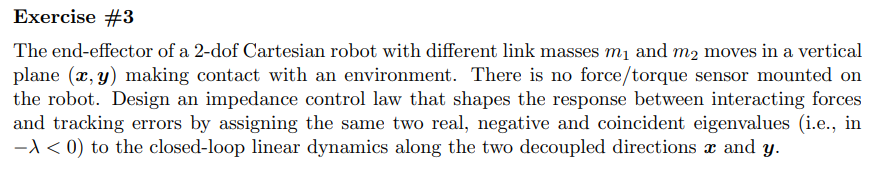


% This part is isolated from previous sectionclear;clc
clear all, close all, clc;
% syms k q1(t) q2(t) q3(t)
sigmaD = [1,1];
n = length(sigmaD);
% t = sym('t', 'real');
q = sym('q_', [n 1],'real');
q_d= sym('q_d_', [n 1],'real');
q_dot = sym('q_dot_', [n 1],'real');
q_ddot = sym('q_ddot_', [n 1],'real');
%
dc = sym('dc', [n 1],'real');
% dc(6)=dc(6)
% k = sym('k', [n 1],'real');
l = sym('l', [n 1],'real');
m = sym('m', [n 1],'real');
m_p = sym('m_p','real');
%m(2)=m(2)+m_p
I = sym('I', [n 1],'real');
% alpha_angle=sym('alpha','real')
g0 = sym('g0','real');
g=[0,-g0,0]';

R2Robot=['pp';'xy';sigmaD]

R2Robot = 3×2 char array
    'pp'
    'xy'
    ''


z = Gen_param(n);
z.sigmaD=R2Robot;
z.l=l;
z.q=q;
z.q_dot=q_dot;
z.q_ddot=q_ddot;

z.g=g;

z.dc=dc;
z.m=m;
z.I=I;
z.methodD=1%2=with DH table, 1 normal mode

z = struct with fields:
                  sigmaD: [3×2 char]
                       l: [2×1 sym]
                      l_: []
                       q: [2×1 sym]
                   q_dot: [2×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [2×1 sym]
                       m: [2×1 sym]
                       I: [2×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: [1×1 sym]
                      rc: []
            movingframes: 0
                       n: 2
                  angle_: [1×2 sym]
               rcdefined: 1
                opt_expr: []
                collides: []
                joint_on: 1
                  xyonly: 0
    prismatic_CoM_method: [1 1]
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
                 ismotor: 0
       

% z.dhTable=dhTable
z.firstParam='alpha';
% z.rc=[]
% z.movingframes=[]
z.angle_=sym(zeros(1,n));
% z.opt_expr={[l(1)+q(2)],[q(2)]};
% z.rcdefined=true;
z.prismatic_CoM_method(2)=2;
z.xyonly=true

z = struct with fields:
                  sigmaD: [3×2 char]
                       l: [2×1 sym]
                      l_: []
                       q: [2×1 sym]
                   q_dot: [2×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [2×1 sym]
                       m: [2×1 sym]
                       I: [2×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: [1×1 sym]
                      rc: []
            movingframes: 0
                       n: 2
                  angle_: [1×2 sym]
               rcdefined: 1
                opt_expr: []
                collides: []
                joint_on: 1
                  xyonly: 1
    prismatic_CoM_method: [1 2]
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
                 ismotor: 0
       

% q = sym('q', [n,1],'real');
% qd= sym('qd', [n,1],'real');
% a = sym('a', [n,1],'real');
% d = sym('d', [n,1],'real');

% z.dhTable = [pi/2    , 0     , z.l(1) , q(1);
%             0       , z.l(2)  , 0   , q(2);]

% 
% [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE2(z)
[Pc,vc,w,T,Ti,M,VarShortRobot,Trans]=getGenericPC2(z)

rcdefined = logical
   1


z = struct with fields:
                  sigmaD: [3×2 char]
                       l: [2×1 sym]
                      l_: []
                       q: [2×1 sym]
                   q_dot: [2×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [2×1 sym]
                       m: [2×1 sym]
                       I: [2×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: [1×1 sym]
                      rc: []
            movingframes: 0
                       n: 2
                  angle_: [1×2 sym]
               rcdefined: 1
                opt_expr: []
                collides: []
                joint_on: 1
                  xyonly: 1
    prismatic_CoM_method: [1 2]
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
                 ismotor: 0
       

si falla aquí está el error


anglerot = 1×1 cell array
    {4×4 sym}


method with PC , pay attention!
moving frames OFF!!


$$Ti = \frac{m_{1}\,{{\dot{q}}_{1}}^{2}}{2}$$

moving frames OFF!!


$$Ti = \left(\begin{array}{cc} \frac{m_{1}\,{{\dot{q}}_{1}}^{2}}{2} & \frac{m_{2}\,\left({{\dot{q}}_{1}}^{2}+{{\dot{q}}_{2}}^{2}\right)}{2} \end{array}\right)$$

$$To\_derive = \left(\begin{array}{cc} 1 & 0\\ 0 & 1\\ 0 & 0 \end{array}\right)$$

$$q\_t = \left(\begin{array}{c} q_{1}\left(t\right)\\ q_{2}\left(t\right) \end{array}\right)$$

    "check the _ last term it is needed for the function for example q_1_ should be the right way to define a varaible to convert to time dependent"



z_derivated = struct with fields:
    dot_t: [3×2 sym]


z_derivated = struct with fields:
     dot_t: [3×2 sym]
    ddot_t: [3×2 sym]


z_derivated = struct with fields:
     dot_t: [3×2 sym]
    ddot_t: [3×2 sym]
    tdot_t: [3×2 sym]


z_derivated = struct with fields:
        dot_t: [3×2 sym]
       ddot_t: [3×2 sym]
       tdot_t: [3×2 sym]
          dot: [3×2 sym]
    dot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2} \end{array}\right)$$

z_derivated = struct with fields:
        dot_t: [3×2 sym]
       ddot_t: [3×2 sym]
       tdot_t: [3×2 sym]
          dot: [3×2 sym]
    dot_short: []


z_derivated = struct with fields:
         dot_t: [3×2 sym]
        ddot_t: [3×2 sym]
        tdot_t: [3×2 sym]
           dot: [3×2 sym]
     dot_short: []
          ddot: [3×2 sym]
    ddot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2} \end{array}\right)$$

z_derivated = struct with fields:
         dot_t: [3×2 sym]
        ddot_t: [3×2 sym]
        tdot_t: [3×2 sym]
           dot: [3×2 sym]
     dot_short: []
          ddot: [3×2 sym]
    ddot_short: []


z_derivated = struct with fields:
         dot_t: [3×2 sym]
        ddot_t: [3×2 sym]
        tdot_t: [3×2 sym]
           dot: [3×2 sym]
     dot_short: []
          ddot: [3×2 sym]
    ddot_short: []
          tdot: [3×2 sym]
    tdot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2} \end{array}\right)$$

z_derivated = struct with fields:
         dot_t: [3×2 sym]
        ddot_t: [3×2 sym]
        tdot_t: [3×2 sym]
           dot: [3×2 sym]
     dot_short: []
          ddot: [3×2 sym]
    ddot_short: []
          tdot: [3×2 sym]
    tdot_short: []


$$Pc = \left(\begin{array}{cc} q_{1} & q_{1}\\ 0 & q_{2}-{\mathrm{dc}}_{2}\\ 0 & 0 \end{array}\right)$$

$$vc = \left(\begin{array}{cc} {\dot{q}}_{1} & {\dot{q}}_{1}\\ 0 & {\dot{q}}_{2}\\ 0 & 0 \end{array}\right)$$

$$w = \left(\begin{array}{cc} 0 & 0\\ 0 & 0\\ 0 & 0 \end{array}\right)$$

$$T = \frac{m_{1}\,{{\dot{q}}_{1}}^{2}}{2}+\frac{m_{2}\,\left({{\dot{q}}_{1}}^{2}+{{\dot{q}}_{2}}^{2}\right)}{2}$$

$$Ti = \left(\begin{array}{cc} \frac{m_{1}\,{{\dot{q}}_{1}}^{2}}{2} & \frac{m_{2}\,\left({{\dot{q}}_{1}}^{2}+{{\dot{q}}_{2}}^{2}\right)}{2} \end{array}\right)$$

$$M = \left(\begin{array}{cc} m_{1}+m_{2} & 0\\ 0 & m_{2} \end{array}\right)$$

VarShortRobot = struct with fields:
    Pc: [3×2 sym]
    vc: [3×2 sym]
     w: [3×2 sym]
     T: [1×1 sym]
    Ti: [1×2 sym]
     M: [2×2 sym]


Trans = struct with fields:
                 TTotal: [4×4 sym]
                PTotali: [3×2 sym]
               TPartial: {[4×4 sym]  [4×4 sym]}
                 RTotal: [3×3 sym]
               RPartial: {[3×3 sym]  [3×3 sym]}
                 PTotal: [3×1 sym]
        Jacobian_PTotal: [3×2 sym]
    Jacobian_dot_PTotal: [3×2 sym]
               PPartial: {[3×1 sym]  [3×1 sym]}
                     Pc: [3×2 sym]
                RTotali: {[3×3 sym]  [3×3 sym]}
           ThetaPartial: [2×1 sym]
             ThetaTotal: [1×1 sym]
                     vc: [3×2 sym]
                      w: [3×2 sym]
                      T: [1×1 sym]
                     Ti: [1×2 sym]
                      M: [2×2 sym]


[Msubs, dynamicParameters, aM] = getDynamicParameters(M,z.q,[])

>> Getting dynamic coefficients. Might take a while...
Only one term in the list of terms


paramscell2 = 1×1 cell array
    {1×1 sym}


MSubs second iteration (before re-replacement)


$$Msubs = \left(\begin{array}{cc} {\mathrm{aa}}_{1} & 0\\ 0 & {\mathrm{aa}}_{2} \end{array}\right)$$

si falla uncomment this line verify  una lineas arriba


$$Msubs = \left(\begin{array}{cc} a_{1} & 0\\ 0 & a_{2} \end{array}\right)$$

$$dynamicParameters = \left(\begin{array}{c} m_{1}+m_{2}\\ m_{2} \end{array}\right)$$

$$aM = \left(\begin{array}{c} a_{1}\\ a_{2} \end{array}\right)$$

% Msubs
% % 
% 
% % PC_EEShort.J
% % PC_EEShort.f

isMotor=false

isMotor = logical
   0


[g_q, PE, U,g_q_short,PE_short] = getGravityWithPc(Pc, z.q, z.l, z.m, z.dc, z.g, isMotor)

*** Computation of Potential Energy (Jacobian-based method) 


$$qall\_sincos\_comb = \left(\begin{array}{cccccc} \sin\left(q_{1}\right) & \sin\left(q_{2}\right) & \sin\left(q_{1}+q_{2}\right) & \cos\left(q_{1}\right) & \cos\left(q_{2}\right) & \cos\left(q_{1}+q_{2}\right) \end{array}\right)$$

$$PE = -g_{0}\,m_{2}\,\left({\mathrm{dc}}_{2}-q_{2}\right)$$

$$PE\_short = -g_{0}\,m_{2}\,\left({\mathrm{dc}}_{2}-q_{2}\right)$$

$$g\_q\_short = \left(\begin{array}{c} 0\\ g_{0}\,m_{2} \end{array}\right)$$

$$g\_q = \left(\begin{array}{c} 0\\ g_{0}\,m_{2} \end{array}\right)$$

$$PE = -g_{0}\,m_{2}\,\left({\mathrm{dc}}_{2}-q_{2}\right)$$

U = 1×2 cell array
    {1×1 sym}    {1×1 sym}


$$g\_q\_short = \left(\begin{array}{c} 0\\ g_{0}\,m_{2} \end{array}\right)$$

$$PE\_short = -g_{0}\,m_{2}\,\left({\mathrm{dc}}_{2}-q_{2}\right)$$

[C,cac,Csubs] = getCs(M,z.q,z.q_dot)

>> Getting  the Christoffel’sym. Might take a while...


C = 1×2 cell array
    {2×2 sym}    {2×2 sym}


$$cac = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

Csubs = 1×2 cell array
    {2×2 sym}    {2×2 sym}


cac

$$cac = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

g_q

$$g\_q = \left(\begin{array}{c} 0\\ g_{0}\,m_{2} \end{array}\right)$$

U{:}

$$ans = 0$$

$$ans = -g_{0}\,m_{2}\,\left({\mathrm{dc}}_{2}-q_{2}\right)$$

% F_v=sym('F',[2,1],'real')
% [All, dynamicParamsReturn, a]= getDynamicParameters([M,diag(g_q),F_v],q,[q_dot.',g0],2)

% %complete model
% Msubs*z.q_ddot+cac+F_v'*z.q_dot%=Tao
Msubs*z.q_ddot+cac+g_q%=Tao

$$ans = \left(\begin{array}{c} a_{1}\,{\ddot{q}}_{1}\\ a_{2}\,{\ddot{q}}_{2}+g_{0}\,m_{2} \end{array}\right)$$

M_inv=pinv(M)

$$M\_inv = \left(\begin{array}{cc} \frac{1}{m_{1}+m_{2}} & 0\\ 0 & \frac{1}{m_{2}} \end{array}\right)$$

s=sym('s','real')

$$s = s$$

lambda=sym('lambda','real')

$$lambda = \lambda$$

Dm=eye(n).* sym('D_m_',[n,1],'real')

$$Dm = \left(\begin{array}{cc} D_{m,1} & 0\\ 0 & D_{m,2} \end{array}\right)$$

Km=eye(n).*sym('K_m_',[n,1],'real')

$$Km = \left(\begin{array}{cc} K_{m,1} & 0\\ 0 & K_{m,2} \end{array}\right)$$


eig_mat= eye(n).*((s+lambda)^2)

$$eig\_mat = \left(\begin{array}{cc} {\left(\lambda +s\right)}^{2} & 0\\ 0 & {\left(\lambda +s\right)}^{2} \end{array}\right)$$

plant_s=eye(n).*s^2+M_inv*Dm*s+M_inv*Km

$$plant\_s = \left(\begin{array}{cc} \frac{K_{m,1}}{m_{1}+m_{2}}+s^{2}+\frac{D_{m,1}\,s}{m_{1}+m_{2}} & 0\\ 0 & \frac{K_{m,2}}{m_{2}}+s^{2}+\frac{D_{m,2}\,s}{m_{2}} \end{array}\right)$$

## solving equations

solve(plant_s==eig_mat)

ans = struct with fields:
    lambda: [0×1 sym]
        m1: [0×1 sym]
        m2: [0×1 sym]
         s: [0×1 sym]
